## Практика 2. Представление сигналов в модели

Пунк 1. 

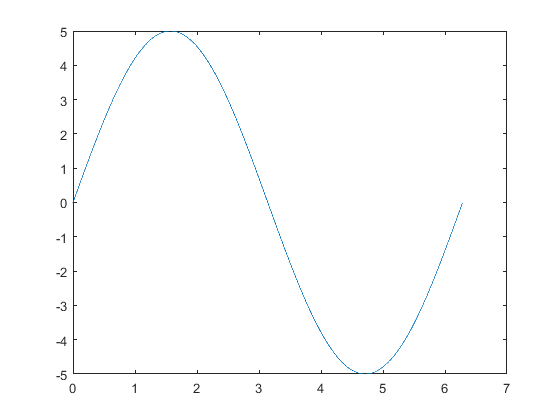

clear all;
amp = 5;
freq = 2.2;
startPhase = 0;
deltaT = 0.001;
duration = 2 * pi;
sinValues = [];
timeValues = [];
for index = 0 : deltaT : duration
    sinValues = [sinValues amp * sin(freq * index + startPhase)];
    timeValues = [timeValues index];
end
plot(timeValues, sinValues);

Пункт 2.

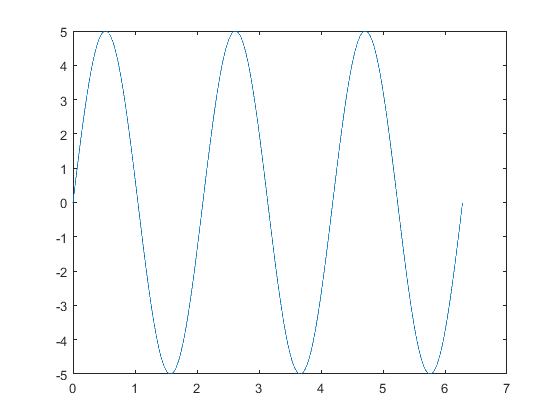

freq = 3;
sinValues = [];
timeValues = [];
for index = 0 : deltaT : 2 * pi
    sinValues = [sinValues amp * sin(freq * index + startPhase)];
    timeValues = [timeValues index];
end
plot(timeValues, sinValues);

Пункт 3.

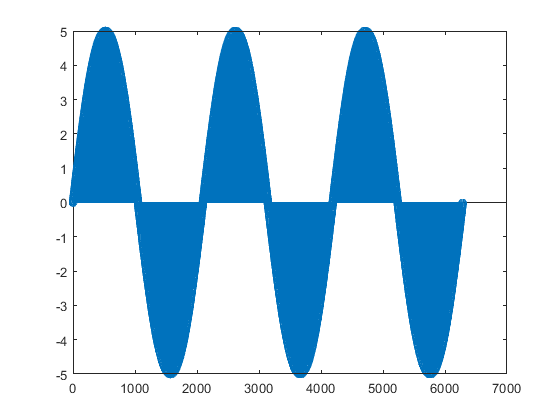

stem(sinValues);

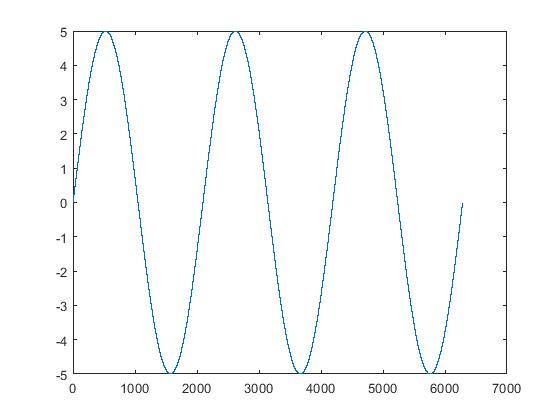

stairs(sinValues);

Пункт 4. 

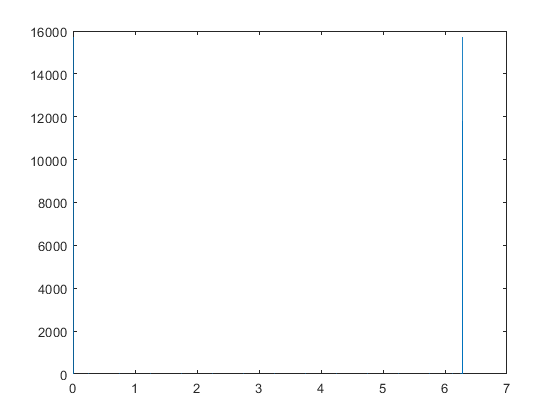

spector = fft(sinValues);
sigAbs = abs(spector);
plot(timeValues, sigAbs);

Пункт 5. 

x = size(timeValues)

x =            1        6284


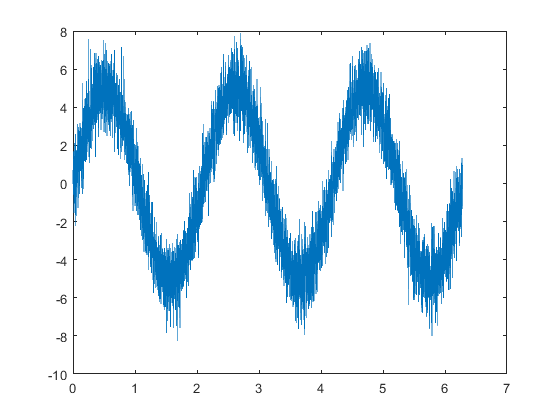

noise = wgn(1, x(2), 0);
sinValuesNoise = sinValues + noise;
plot(timeValues, sinValuesNoise);

Пункт 6. 

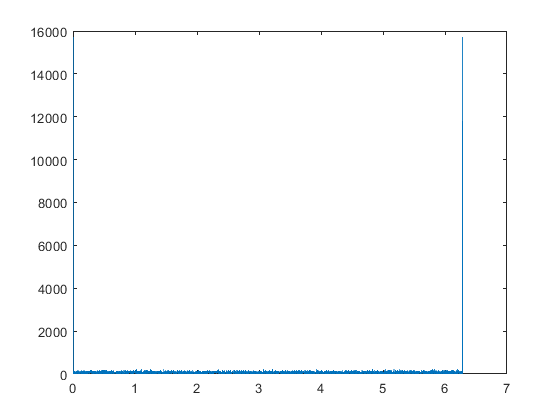

spectorNoise = fft(sinValuesNoise);
sigAbsNoise = abs(spectorNoise);
plot(timeValues, sigAbsNoise);

Пункт 7. 

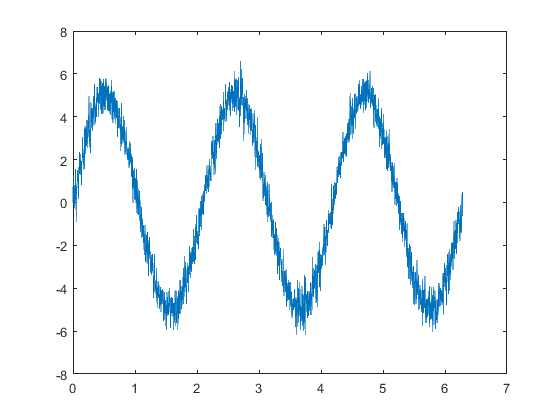

L = 5;
sinValuesNoiseFilter = zeros(1, x(2));
for index = 1 : 1 : L
    sinValuesNoiseFilter(index)  = sinValuesNoise(1, index);
end

for indexX = L : 1 : x(2)
    localSumm = 0;
    for indexY = indexX : -1 : indexX - L + 1
        localSumm = localSumm + sinValuesNoise(1, indexY);
    end
    summ = localSumm / L;
    sinValuesNoiseFilter(indexX)  = summ;
end
plot(timeValues, sinValuesNoiseFilter);

Пункт 8.

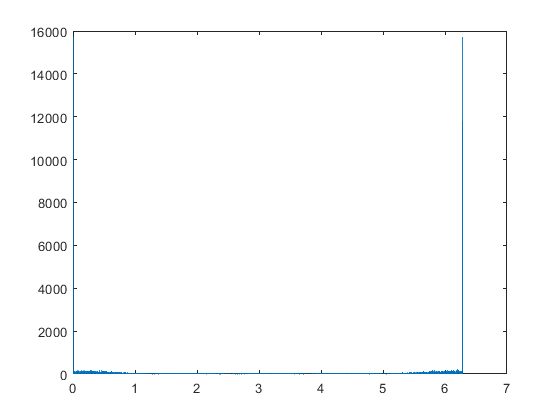

spectorNoiseFilter = fft(sinValuesNoiseFilter);
sigAbsNoiseFilter = abs(spectorNoiseFilter);
plot(timeValues, sigAbsNoiseFilter);

Пункт 9.

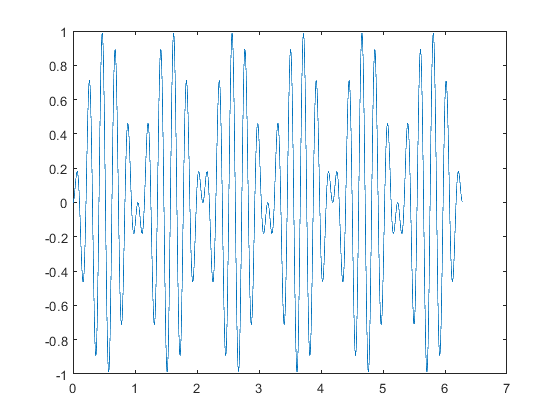

freq = 30;
sinValuesD = [];
timeValuesD = [];
for index = 0 : deltaT : 2 * pi
    val = sin(3 * index)* sin(freq * index + startPhase);
    sinValuesD = [sinValuesD  val];
    timeValuesD = [timeValuesD index];
end
plot(timeValuesD, sinValuesD);

Пункт 10.

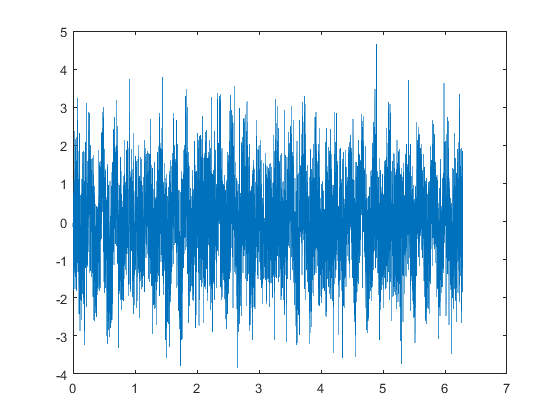

noise = wgn(1, x(2), 0);
sinValuesNoiseD = sinValuesD + noise;
plot(timeValuesD, sinValuesNoiseD);

Пункт 11.

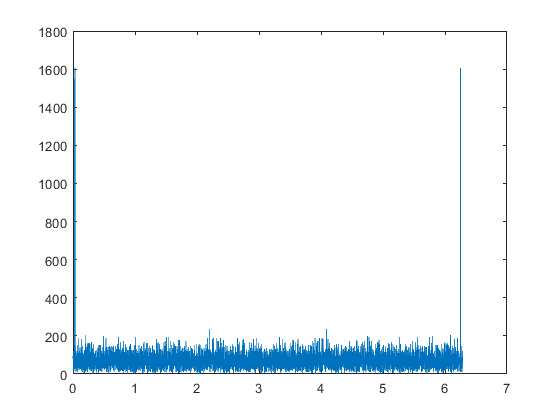

spectorNoiseFilterD = fft(sinValuesNoiseD);
sigAbsNoiseFilterD = abs(spectorNoiseFilterD);
plot(timeValuesD, sigAbsNoiseFilterD);

Пункт 12.

signal = sinValuesNoiseD + sinValuesD

signal =    -0.0476   -0.1481    0.1558    0.4513   -1.0013    0.6785   -0.0466   -1.7680   -0.6001    0.0907    0.4577    0.6404    0.3818    0.7955    0.2606   -0.3734    1.1043    0.1001   -0.0245   -1.0994    0.8717   -0.6916    0.9435   -1.1969    0.3255   -0.2987    0.0199   -1.2814   -0.4349    1.0915    2.4464    0.8433   -1.6956   -0.3025    0.5908   -0.5075    2.2512    0.1379    1.4918    0.5006    0.2962    2.0651   -0.9641   -0.2501   -1.3155    0.5396    0.7005    0.8108    1.3475   -0.9972


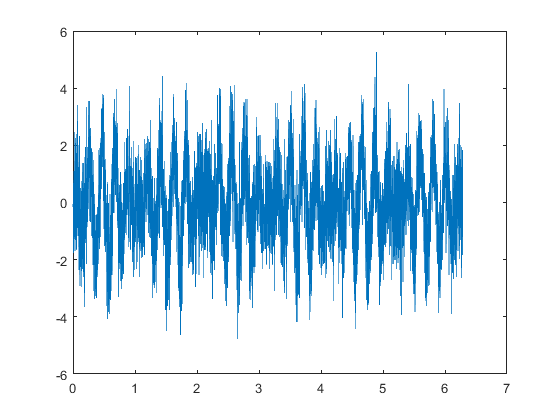

plot(timeValuesD, signal);

Пункт 13.

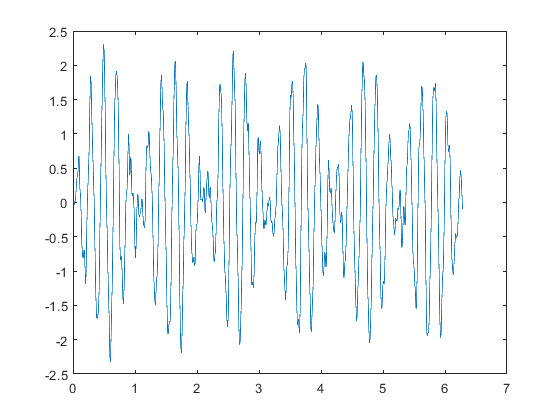

[b, a] = butter(4,0.04,'low');
dataOut = filter(b,a,signal);
plot(timeValuesD, dataOut);